# DSP Lab - Homework3

#### Mahdi Mahjouri Namin 40023125

#### Nima Nourizadeh 40023086

clc;
clear;
close all;

### Section 2-1(a)

% Check if x*h == h*x
% !! Function is available at the end of the code !!
x = [1 2 3];
h = [4 5 6];

y1 = myconv(x, h);
y2 = myconv(h, x);

disp('x * h = '); disp(y1);

x * h = 
    18     4    13    28    27



disp('h * x = '); disp(y2);

h * x = 
    18     4    13    28    27



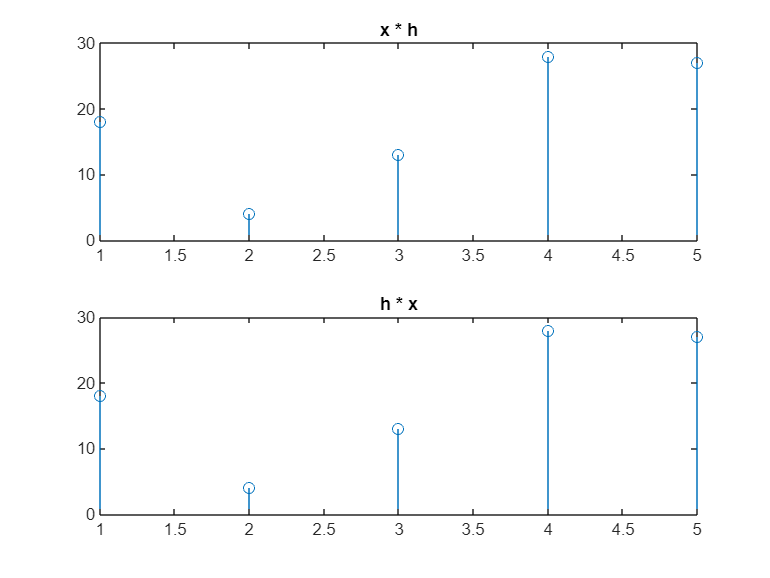


figure;
subplot(2,1,1); stem(y1); title('x * h');
subplot(2,1,2); stem(y2); title('h * x');

### Section 2-1(b)

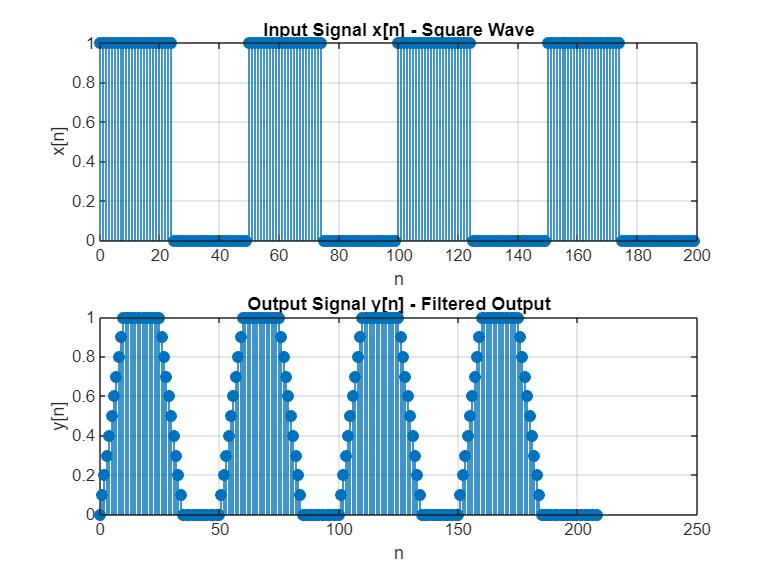

% Input square wave signal
L = 200;       % Total length
K = 50;        % Period
halfK = K / 2;

% Generate square wave: 25 ones, 25 zeros repeated
x = repmat([ones(1, halfK), zeros(1, halfK)], 1, L / K);

% Pseudo-integrator impulse response
h = 0.1 * ones(1, 10);  % 10-point moving average

% Convolve using myconv function
y = myconv(x, h);

% Plot input and output
n1 = 0:length(x)-1;
n2 = 0:length(y)-1;

figure;
subplot(2,1,1);
stem(n1, x, 'filled'); grid on;
title('Input Signal x[n] - Square Wave');
xlabel('n'); ylabel('x[n]');

subplot(2,1,2);
stem(n2, y, 'filled'); grid on;
title('Output Signal y[n] - Filtered Output');
xlabel('n'); ylabel('y[n]');

- The filter **smooths** the transitions in the square wave, producing a **ramp-up and ramp-down** effect rather than sharp edges.

- This behavior is typical of **low-pass filters**, which suppress high-frequency components (like sharp transitions).

- The output rises linearly when the input is high and falls linearly when the input goes low, due to the **accumulation** effect of the moving average.

### Section 2-1(c)

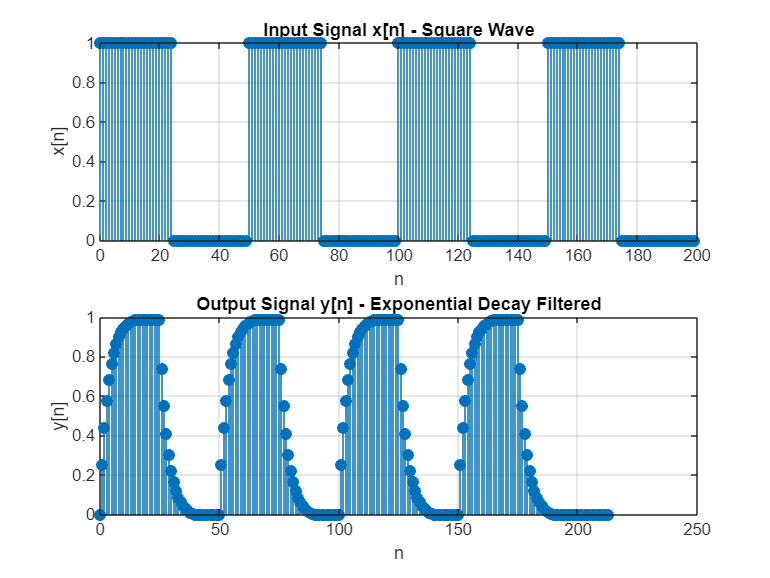


% Input signal
L = 200;
K = 50;
halfK = K / 2;
x = repmat([ones(1, halfK), zeros(1, halfK)], 1, L / K);

% Exponential decay impulse response
n = 0:14;
h = 0.25 * (0.75).^n;

% Convolve using custom myconv
y = myconv(x, h);

% Plot input and output
n1 = 0:length(x)-1;
n2 = 0:length(y)-1;

figure;
subplot(2,1,1);
stem(n1, x, 'filled'); grid on;
title('Input Signal x[n] - Square Wave');
xlabel('n'); ylabel('x[n]');

subplot(2,1,2);
stem(n2, y, 'filled'); grid on;
title('Output Signal y[n] - Exponential Decay Filtered');
xlabel('n'); ylabel('y[n]');

- The output again smooths the transitions, but compared to the previous filter, this one:

- Rises and falls **more gradually**

- Has a **non-linear slope**, starting steep and then flattening

- Retains the memory of past samples with **exponentially decreasing weight**

- It behaves like a **first-order IIR filter** in structure, but here it's FIR because it stops at n = 14

### Section 2-1(d)

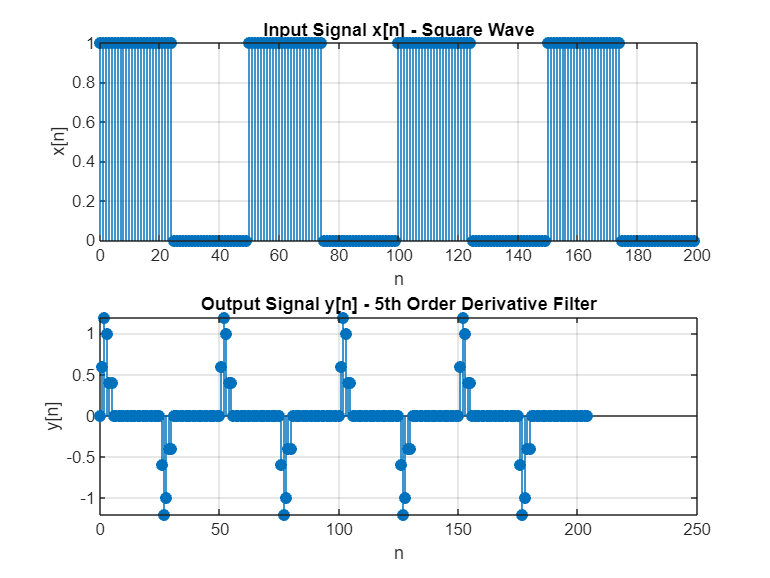


% Input signal
L = 200;
K = 50;
halfK = K / 2;
x = repmat([ones(1, halfK), zeros(1, halfK)], 1, L / K);

% 5th-order derivative filter
% h[n] = 0.2 * conv(conv(conv(conv([1, -1], [1, -1]), ...), ...)
h1 = [1, -1];
h = h1;
for i = 1:4
    h = myconv(h, h1);
end
h = 0.2 * h;

% Apply convolution using myconv
y = myconv(x, h);

% Plot input and output
n1 = 0:length(x)-1;
n2 = 0:length(y)-1;

figure;
subplot(2,1,1);
stem(n1, x, 'filled'); grid on;
title('Input Signal x[n] - Square Wave');
xlabel('n'); ylabel('x[n]');

subplot(2,1,2);
stem(n2, y, 'filled'); grid on;
title('Output Signal y[n] - 5th Order Derivative Filter');
xlabel('n'); ylabel('y[n]');

- Since the filter acts as a **high-order differentiator**, it primarily highlights the **edges** or **sudden transitions** in the square wave input.

- The output has non-zero values **only at the points where the input changes** from 0 to 1 or from 1 to 0, while it remains nearly zero elsewhere.

- This behavior confirms that the 5th-order derivative filter is well-suited for detecting **sharp changes** or **discontinuities** in signals, such as edges.

### Section 2-2(a)

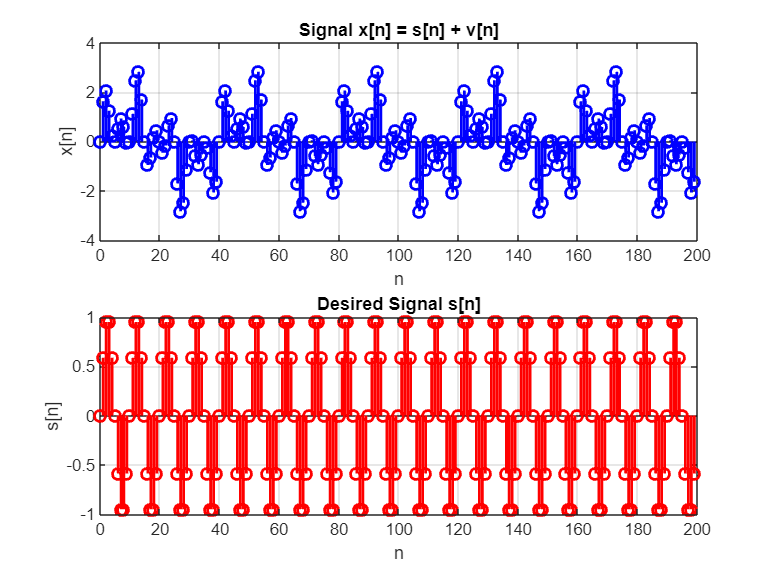

% Define parameters
omega1 = 0.05 * pi;
omega2 = 0.20 * pi;
omega3 = 0.35 * pi;
M = 100; % Filter order
N = 200; % Number of samples
n = 0:N-1; % Sample indices

% Define signals
s = sin(omega2 * n); % Desired signal
v = sin(omega1 * n) + sin(omega3 * n); % Interference
x = s + v; % Combined signal

% Plot the signals
figure;
subplot(2,1,1);
stem(n, x, 'b', 'LineWidth', 1.5);
title('Signal x[n] = s[n] + v[n]');
xlabel('n');
ylabel('x[n]');
grid on;

subplot(2,1,2);
stem(n, s, 'r', 'LineWidth', 1.5);
title('Desired Signal s[n]');
xlabel('n');
ylabel('s[n]');
grid on;

### Section 2-2(b)

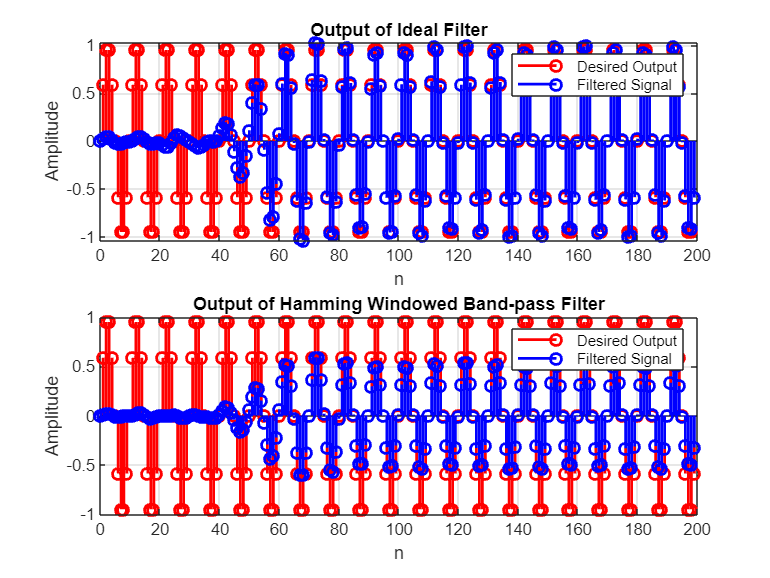

% Define parameters
omega1 = 0.05 * pi;
omega2 = 0.20 * pi;
omega3 = 0.35 * pi;
M = 100; % Filter order
N = 200; % Number of samples
n = 0:N-1; % Sample indices

% Define signals
s = sin(omega2 * n); % Desired signal
v = sin(omega1 * n) + sin(omega3 * n);
x = s + v; % Combined signal

% Define the FIR filter h[n] using the given specifications
omega_a = 0.15 * pi; % Lower cutoff frequency
omega_b = 0.25 * pi; % Upper cutoff frequency

% Design the ideal filter response
n_ideal = (0:M) - M/2; % Adjust n_ideal to match filter size
h_ideal = (sin(omega_b * n_ideal) - sin(omega_a * n_ideal)) ./ (pi * n_ideal);

% Handle division by zero at n_ideal = 0
h_ideal(M/2 + 1) = (omega_b - omega_a) / pi;

% Apply the Hamming window
w = 0.54 - 0.46 * sin(2 * pi * (0:M) / M);

% Ideal filter output
y_ideal = filter(h_ideal, 1, x); % Output of the ideal filter

% Hamming windowed BPF output
h = h_ideal .* w; % FIR filter impulse response with Hamming window
y_hamming = filter(h, 1, x); % Output of the Hamming windowed filter

% Plot the outputs using subplot
figure;

% Plot the output of the ideal filter
subplot(2,1,1);
stem(n, s, 'r', 'LineWidth', 1.5); 
hold on;
stem(n, y_ideal(1:N), 'b', 'LineWidth', 1.5); % Plot ideal filter output
title('Output of Ideal Filter');
xlabel('n');
ylabel('Amplitude');
grid on;
legend("Desired Output","Filtered Signal")

% Plot the output of the Hamming windowed BPF
subplot(2,1,2);
stem(n, s, 'r', 'LineWidth', 1.5); 
hold on;
stem(n, y_hamming(1:N), 'b', 'LineWidth', 1.5); % Plot Hamming windowed filter output
title('Output of Hamming Windowed Band-pass Filter');
xlabel('n');
ylabel('Amplitude');
grid on;
legend("Desired Output","Filtered Signal")

### Section 2-2(c)

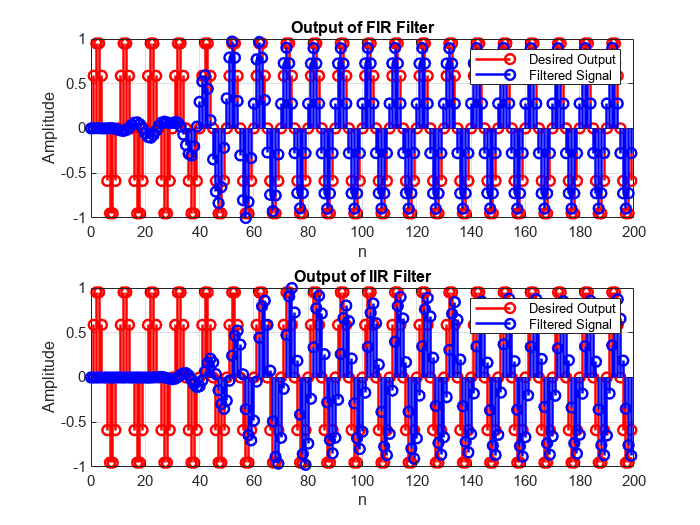



% FIR Filter design (using HW3_FIR function)
fir_filter = HW3_FIR(); % Obtain the FIR filter object
fir_b = fir_filter.Numerator;
% IIR Filter design (using HW3_IIR function)
iir_filter = HW3_IIR(); % Obtain the IIR filter object
sosMatrix = iir_filter.sosMatrix; % Extract the SOS matrix from IIR filter
scaleValues = iir_filter.ScaleValues;

% Filter the signal with FIR filter (FIR filter coefficients as a vector)
y_fir = filter(fir_b, 1, x); % Apply FIR filter to the signal

% Filter the signal with IIR filter (using SOS matrix)
y_iir = sosfilt(sosMatrix, x); % Apply IIR filter to the signal using SOS matrix
y_iir = y_iir / max(abs(y_iir));
% Plot the outputs using subplot
figure;

% Plot the output of the FIR filter
subplot(2,1,1);
stem(n, s, 'r', 'LineWidth', 1.5); 
hold on;
stem(n, y_fir(1:N), 'b', 'LineWidth', 1.5); % Plot FIR filter output
title('Output of FIR Filter');
xlabel('n');
ylabel('Amplitude');
grid on;
legend("Desired Output","Filtered Signal")

% Plot the output of the IIR filter
subplot(2,1,2);
stem(n, s, 'r', 'LineWidth', 1.5); 
hold on;
stem(n, y_iir(1:N), 'b', 'LineWidth', 1.5); % Plot IIR filter output
title('Output of IIR Filter');
xlabel('n');
ylabel('Amplitude');
grid on;
legend("Desired Output","Filtered Signal")

### myconv function

function y = myconv(x, h)
    % Inputs: x - input signal, h - impulse response
    % Output: y - convolution result

    Nx = length(x);
    Nh = length(h);
    Ny = Nx + Nh - 1;

    % Zero-padding the signals
    x_padded = [x, zeros(1, Nh - 1)];
    h_flipped = fliplr(h);                      % Flip h for convolution
    h_padded = [zeros(1, Nx - 1), h_flipped];    % Pad h to match output length

    y = zeros(1, Ny); % Preallocate output

    for n = 1:Ny
        h_shifted = circshift(h_padded, [0, n - 1]); % Shift flipped h
        y(n) = sum(x_padded .* h_shifted);           % Compute dot product
    end
end

